Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

**PROBLEM 1**

**a) Identify univariate and multivariate outliers and determine whether there is the need to take any action about them. **

Podemos eliminar la fila 9 por los siguientes motivos:

Según la siguiente fuente: [https://pubmed.ncbi.nlm.nih.gov/33352671/](https://pubmed.ncbi.nlm.nih.gov/33352671/) los niveles de dioxina deberian estar entre 0.53 +- 0.12 y en nuestros datos encontramos un valor inferior a 0.1.

Además, viendo los valores de la tabla no consideramos que sea normal un valor de 0 en Dieldrin.

Finalmente, no nos cuadra un valor negativo de un componente, como pasa en el caso del HCH de esta fila, el mínimo debería ser 0.

Por todos estos motivos, consideramos la fila 9 un outlier y la eliminamos.

SM22Lab1Salmon2(9,:) = [] 

SM22Lab1Salmon2 = 51×6 table
      Location        HCH     HEpoxide    Dieldrin    Endrin    Dioxin
    _____________    _____    ________    ________    ______    ______

    Faroe Islands    0.133     0.688        3.87       0.48     0.676 
    Faroe Islands    0.141     0.701        4.11      0.479     0.671 
    Faroe Islands    0.145     0.729        4.38      0.502     0.695 
    Faroe Islands    0.275     0.957        5.98      0.404     0.904 
    Faroe Islands    0.265      0.88        5.73      0.385     0.863 
    Faroe Islands    0.249     0.783        5.37      0.364     0.615 
    Faroe Islands    0.215     0.813        5.01      0.708     0.589 
    Faroe Islands    0.219      0.81        4.67      0.679     0.631 
    Faroe Islands    0.199     0.743        4.48      0.

**b) Assess univariate normality of each dimension individually. **

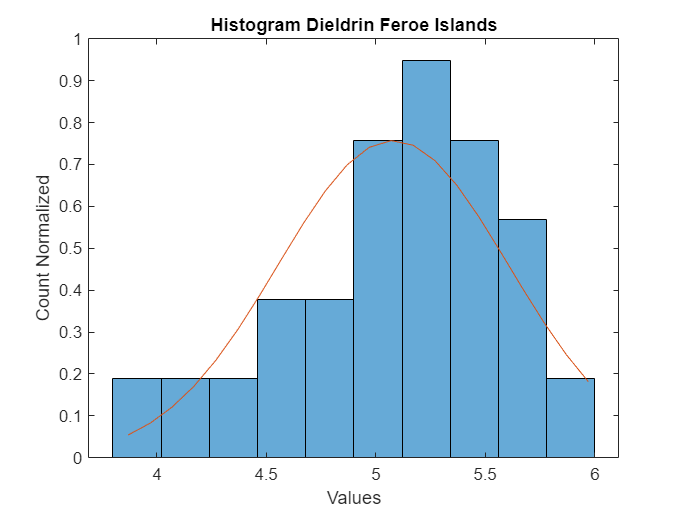

% Primeramente, separamos los datos de las Islas Feroe y Escocia de cada dimensión. 
% Seguidamente, calcularemos la media y la standard deviation de
% cada dimensión para cada populación.

x1_feroe = SM22Lab1Salmon2.Dieldrin(1:24,:);
mean_x1_f = mean(x1_feroe);
std_x1_f = std(x1_feroe);

x2_feroe = SM22Lab1Salmon2.Dioxin(1:24,:);
mean_x2_f = mean(x2_feroe);
std_x2_f = std(x2_feroe);

x3_feroe = SM22Lab1Salmon2.HCH(1:24,:);
mean_x3_f = mean(x3_feroe);
std_x3_f = std(x3_feroe);

x4_feroe = SM22Lab1Salmon2.HEpoxide(1:24,:);
mean_x4_f = mean(x4_feroe);
std_x4_f = std(x4_feroe);

x5_feroe = SM22Lab1Salmon2.Endrin(1:24,:);
mean_x5_f = mean(x5_feroe);
std_x5_f = std(x5_feroe);

x1_scotland = SM22Lab1Salmon2.Dieldrin(25:51,:);
mean_x1_s = mean(x1_scotland);
std_x1_s = std(x1_scotland);

x2_scotland = SM22Lab1Salmon2.Dioxin(25:51,:);
mean_x2_s = mean(x2_scotland);
std_x2_s = std(x2_scotland);

x3_scotland = SM22Lab1Salmon2.HCH(25:51,:);
mean_x3_s = mean(x3_scotland);
std_x3_s = std(x3_scotland);

x4_scotland = SM22Lab1Salmon2.HEpoxide(25:51,:);
mean_x4_s = mean(x4_scotland);
std_x4_s = std(x4_scotland);

x5_scotland = SM22Lab1Salmon2.Endrin(25:51,:);
mean_x5_s = mean(x5_scotland);
std_x5_s = std(x5_scotland);

% Calculamos la n de cada populación, lo cual nos será útil.
n_f = length(SM22Lab1Salmon2.Dieldrin(1:24,:));
n_s = length(SM22Lab1Salmon2.Dieldrin(25:51,:));

% Calculamos los quartiles teóricos tanto de las Islas Feroe como de Escocia
% para usarlos en el momento de hacer el QQ-plot.
q_f = norminv([0.5:n_f-0.5]/n_f);
q_s = norminv([0.5:n_s-0.5]/n_s);

% Dibujamos tanto el histograma con su pdf como el QQ-Plot de cada una de
% las dimensiones para cada una de las localizaciones. En el caso de que
% encontremos una linea recta en el QQ-Plot, sabremos que esa dimensión es
% "univariate".

% Feroe Islands
histogram(x1_feroe, 10, 'Normalization','pdf');
xline_x1_f = [min(x1_feroe):.1:max(x1_feroe)];
hold on
title('Histogram Dieldrin Feroe Islands');
xlabel('Values'); 
ylabel('Count Normalized');
y_x1_f = normpdf(xline_x1_f, mean_x1_f, std_x1_f);
plot(xline_x1_f, y_x1_f);
hold off

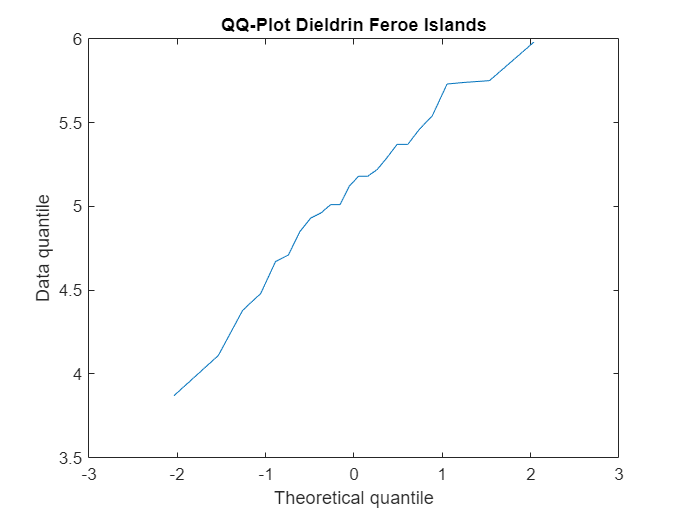


plot(q_f, sort(x1_feroe));
hold on
title('QQ-Plot Dieldrin Feroe Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

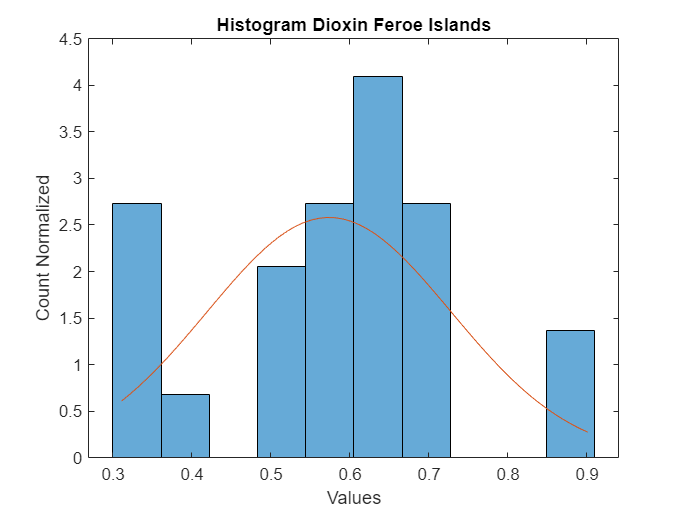


histogram(x2_feroe, 10, 'Normalization','pdf');
xline_x2_f = [min(x2_feroe):.01:max(x2_feroe)];
hold on
title('Histogram Dioxin Feroe Islands');
xlabel('Values'); 
ylabel('Count Normalized');
y_x2_f = normpdf(xline_x2_f, mean_x2_f, std_x2_f);
plot(xline_x2_f, y_x2_f);
hold off

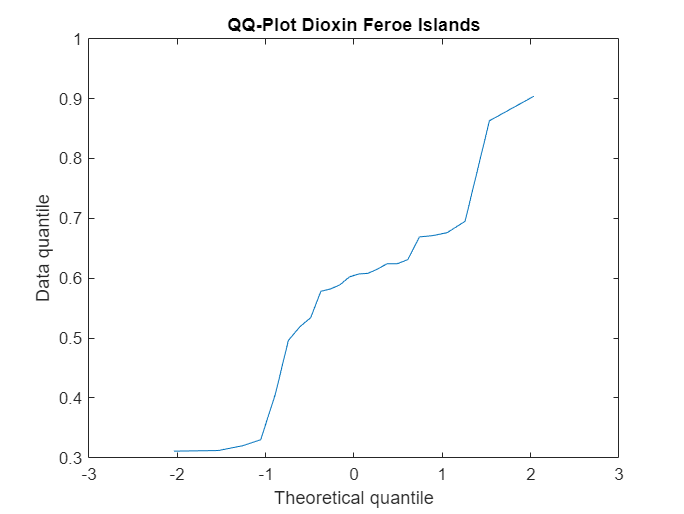


plot(q_f, sort(x2_feroe));
hold on
title('QQ-Plot Dioxin Feroe Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

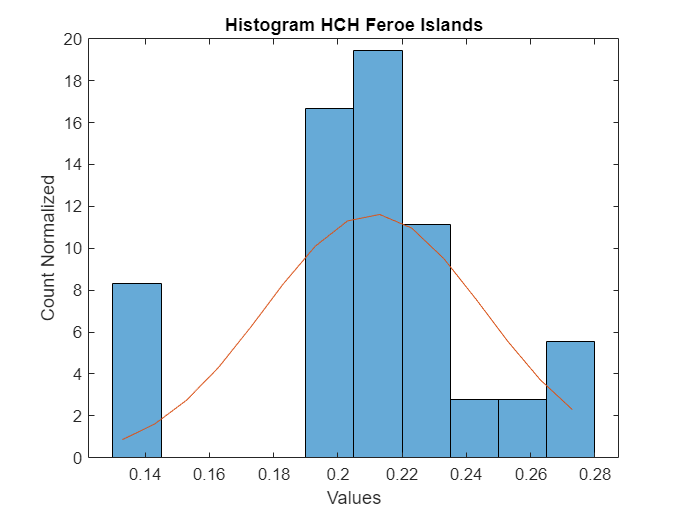


histogram(x3_feroe, 10, 'Normalization','pdf');
xline_x3_f = [min(x3_feroe):.01:max(x3_feroe)];
hold on
title('Histogram HCH Feroe Islands');
xlabel('Values'); 
ylabel('Count Normalized');
y_x3_f = normpdf(xline_x3_f, mean_x3_f, std_x3_f);
plot(xline_x3_f, y_x3_f);
hold off

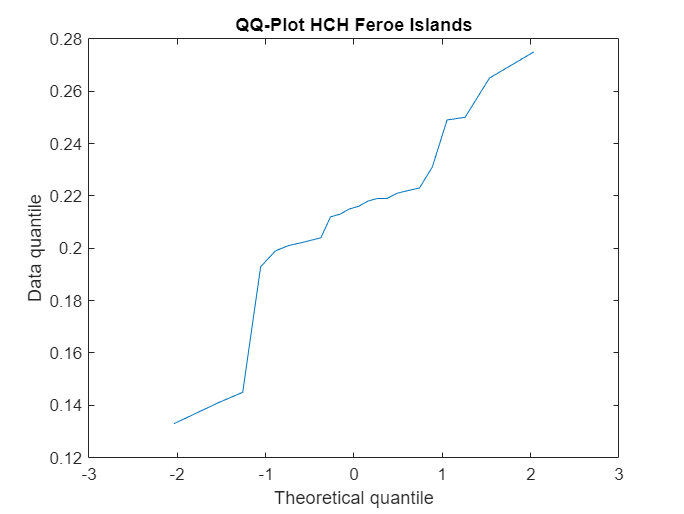


plot(q_f, sort(x3_feroe));
hold on
title('QQ-Plot HCH Feroe Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

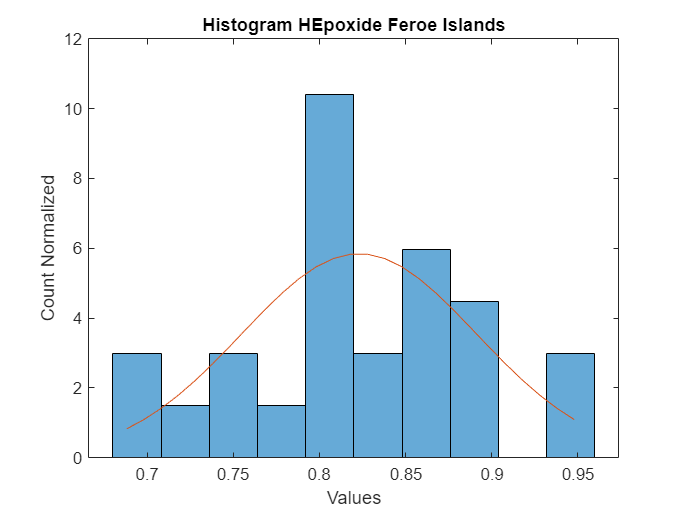


histogram(x4_feroe, 10, 'Normalization','pdf');
xline_x4_f = [min(x4_feroe):.01:max(x4_feroe)];
hold on
title('Histogram HEpoxide Feroe Islands');
xlabel('Values'); 
ylabel('Count Normalized');
y_x4_f = normpdf(xline_x4_f, mean_x4_f, std_x4_f);
plot(xline_x4_f, y_x4_f);
hold off

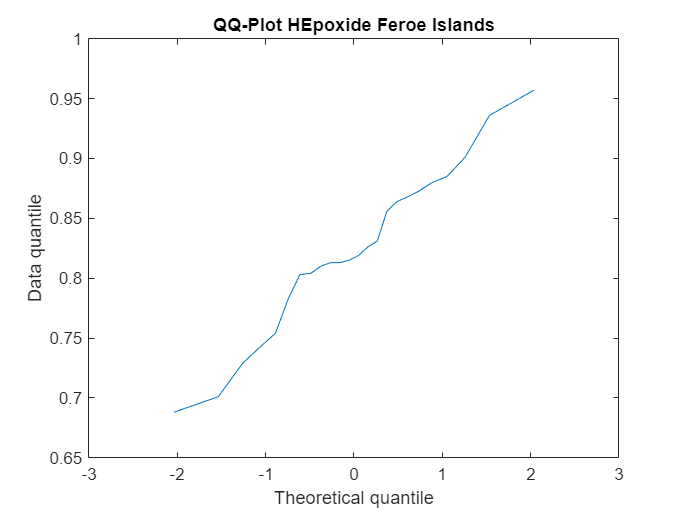


plot(q_f, sort(x4_feroe));
hold on
title('QQ-Plot HEpoxide Feroe Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

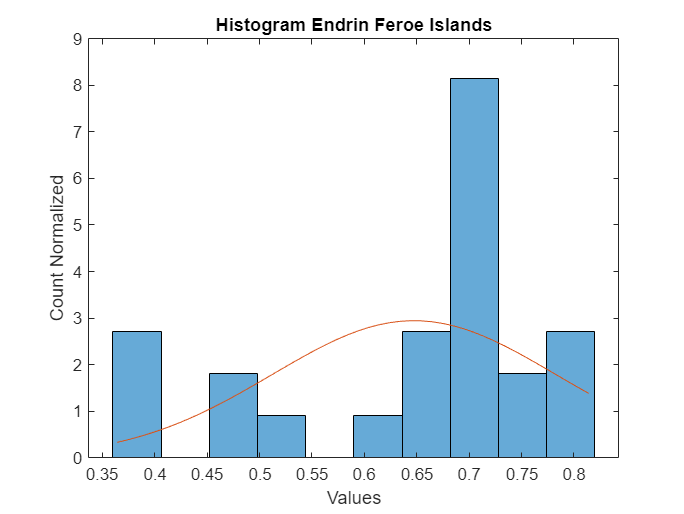


histogram(x5_feroe, 10, 'Normalization','pdf');
xline_x5_f = [min(x5_feroe):.01:max(x5_feroe)];
hold on
title('Histogram Endrin Feroe Islands');
xlabel('Values'); 
ylabel('Count Normalized');
y_x5_f = normpdf(xline_x5_f, mean_x5_f, std_x5_f);
plot(xline_x5_f, y_x5_f);
hold off

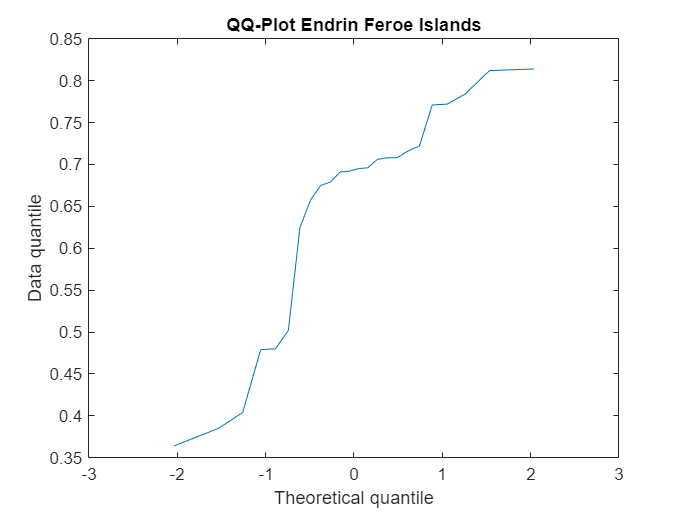


plot(q_f, sort(x5_feroe));
hold on
title('QQ-Plot Endrin Feroe Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

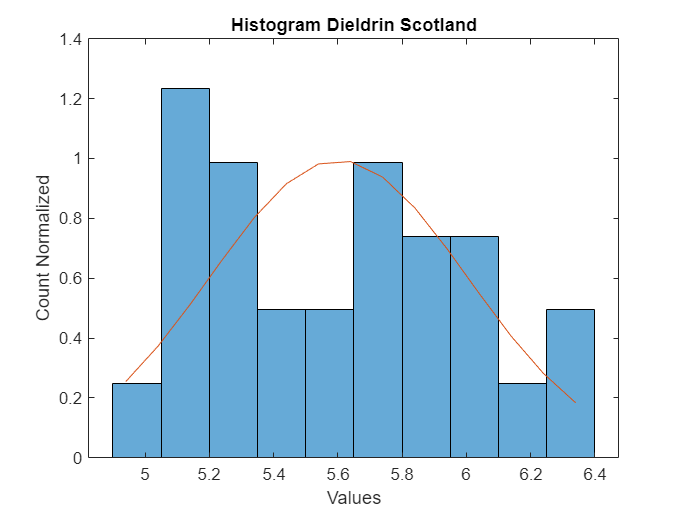


% Scotland
histogram(x1_scotland, 10, 'Normalization','pdf');
xline_x1_s = [min(x1_scotland):.1:max(x1_scotland)];
hold on
title('Histogram Dieldrin Scotland');
xlabel('Values'); 
ylabel('Count Normalized');
y_x1_s = normpdf(xline_x1_s, mean_x1_s, std_x1_s);
plot(xline_x1_s, y_x1_s);
hold off

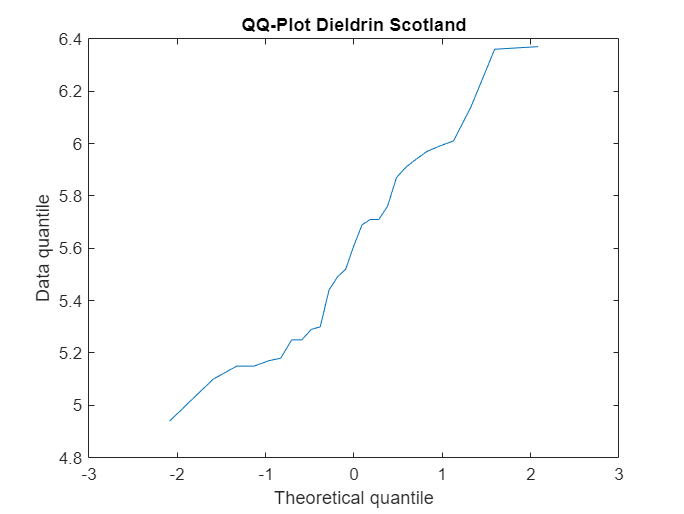


plot(q_s, sort(x1_scotland));
hold on
title('QQ-Plot Dieldrin Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

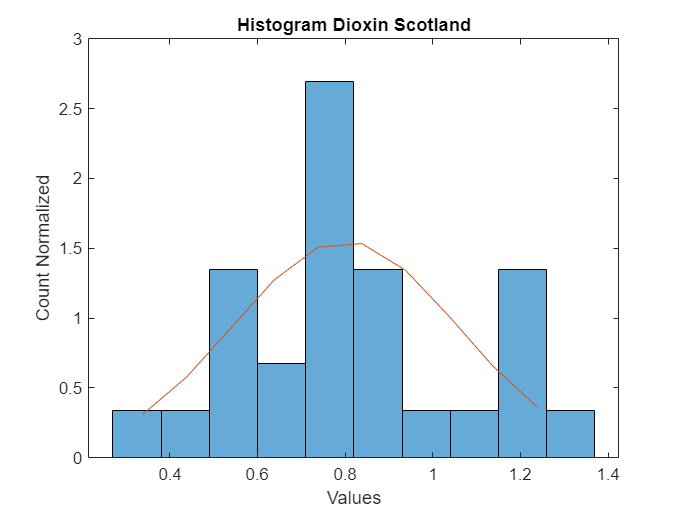


histogram(x2_scotland, 10, 'Normalization','pdf');
xline_x2_s = [min(x2_scotland):.1:max(x2_scotland)];
hold on
title('Histogram Dioxin Scotland');
xlabel('Values'); 
ylabel('Count Normalized');
y_x2_s = normpdf(xline_x2_s, mean_x2_s, std_x2_s);
plot(xline_x2_s, y_x2_s);
hold off

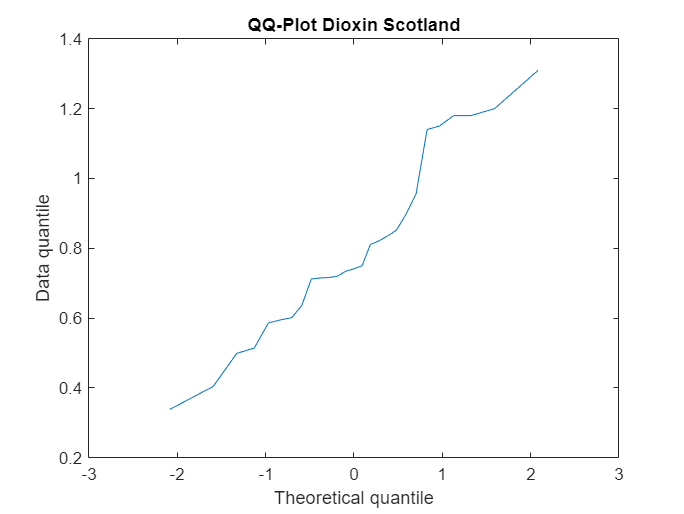


plot(q_s, sort(x2_scotland));
hold on
title('QQ-Plot Dioxin Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

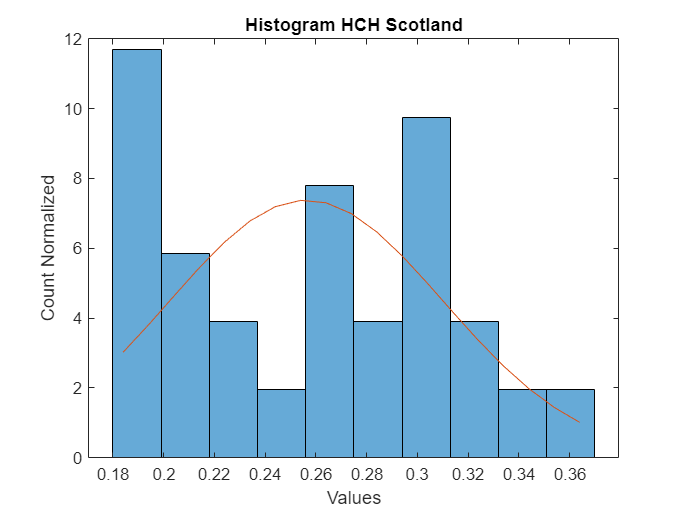


histogram(x3_scotland, 10, 'Normalization','pdf');
xline_x3_s = [min(x3_scotland):.01:max(x3_scotland)];
hold on
title('Histogram HCH Scotland');
xlabel('Values'); 
ylabel('Count Normalized');
y_x3_s = normpdf(xline_x3_s, mean_x3_s, std_x3_s);
plot(xline_x3_s, y_x3_s);
hold off

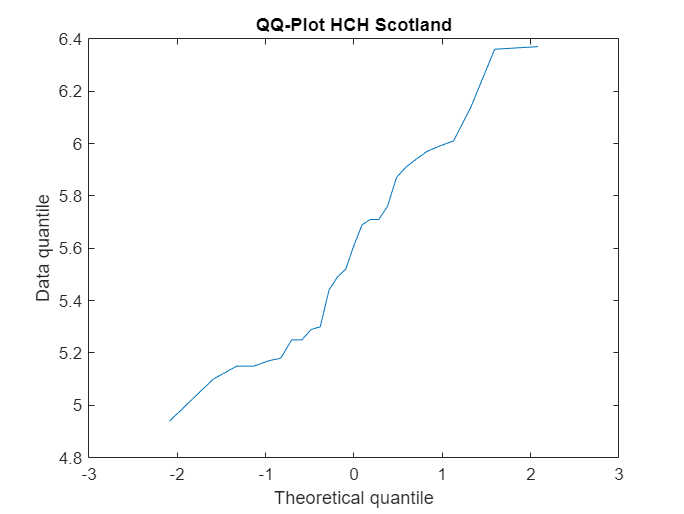


plot(q_s, sort(x1_scotland));
hold on
title('QQ-Plot HCH Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

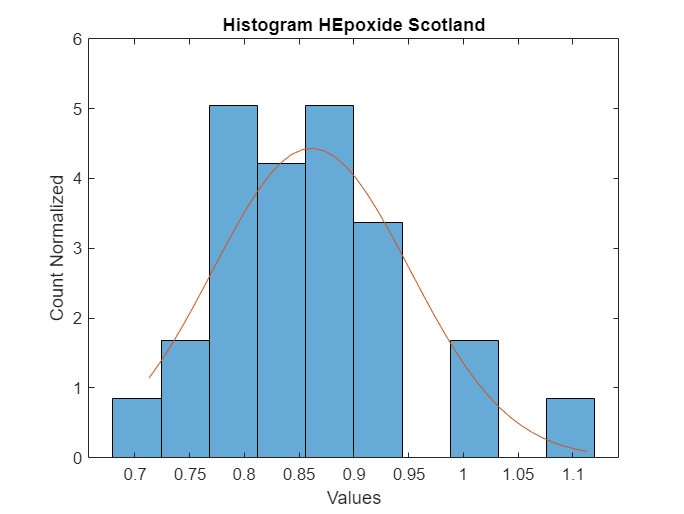


histogram(x4_scotland, 10, 'Normalization','pdf');
xline_x4_s = [min(x4_scotland):.01:max(x4_scotland)];
hold on
title('Histogram HEpoxide Scotland');
xlabel('Values'); 
ylabel('Count Normalized');
y_x4_s = normpdf(xline_x4_s, mean_x4_s, std_x4_s);
plot(xline_x4_s, y_x4_s);
hold off

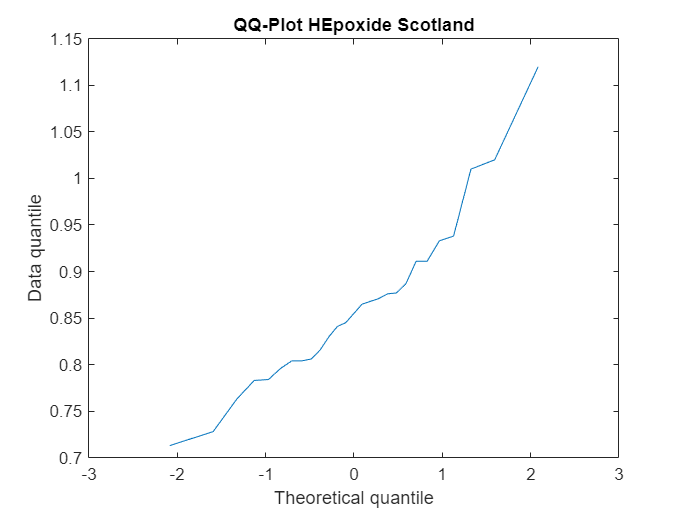


plot(q_s, sort(x4_scotland));
hold on
title('QQ-Plot HEpoxide Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

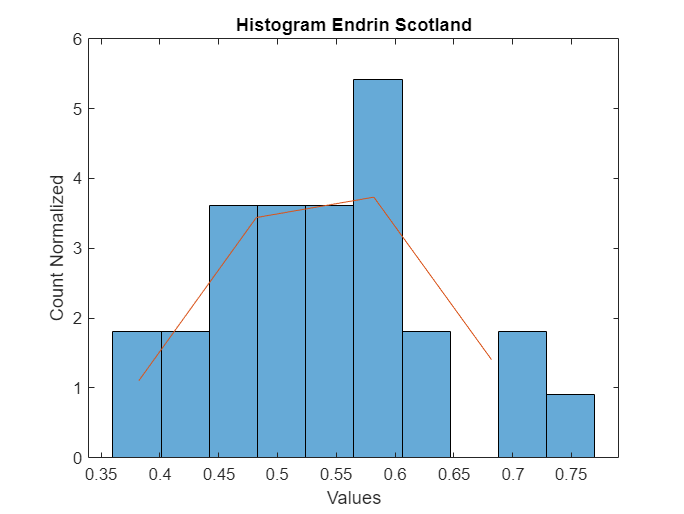


histogram(x5_scotland, 10, 'Normalization','pdf');
xline_x5_s = [min(x5_scotland):.1:max(x5_scotland)];
hold on
y_x5_s = normpdf(xline_x5_s, mean_x5_s, std_x5_s);
plot(xline_x5_s, y_x5_s);
title('Histogram Endrin Scotland');
xlabel('Values'); 
ylabel('Count Normalized');
hold off

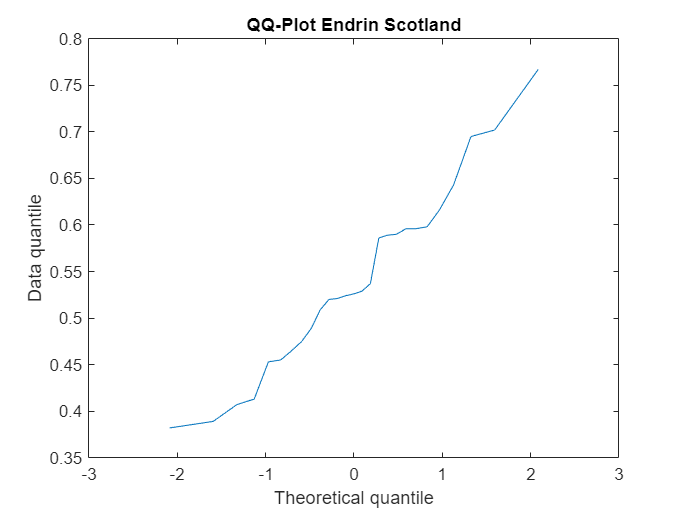


plot(q_s, sort(x5_scotland));
hold on
title('QQ-Plot Endrin Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

Las dimensiones que más parecen tener "univariate normality" son la 1a, 3a, 4a y 5a. Pese a que en algún caso, la linea no sea del todo recta. Esto puede suceder por el bajo número de datos, por ello, daremos por posible esas dimensiones.

**c) Assess bi-variate normality for any pair of dimensions that are not rejected for univariate normality. **

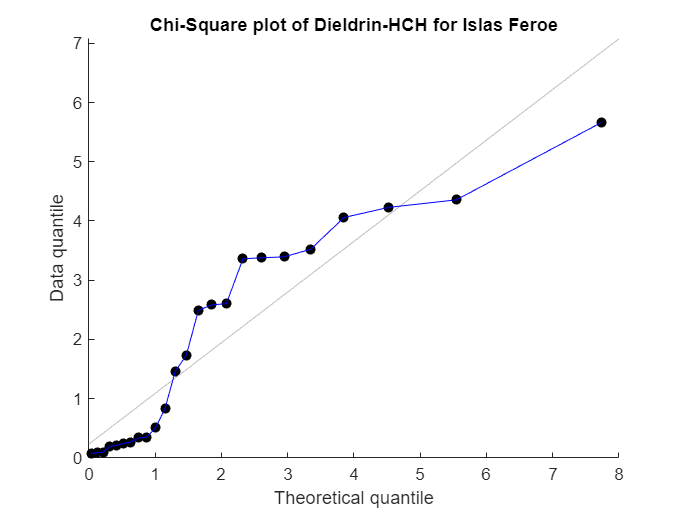

% Calculamos el valor de chi square de cada localización para testearlas.
q_chi_f = chi2inv([0.5:n_f-0.5]/n_f, 2);
q_chi_s = chi2inv([0.5:n_s-0.5]/n_s, 2);

% Dibujamos el Chi-Square entre cada par de dimensiones que hemos considerado
% "univariate" para las Islas Feroe y Escocia. En caso de que los puntos
% sigan una línea lo más similar a recta, consideraremos que estás
% dimensiones son "bivariate" entre ellas. Finalmente, para comprobar del
% todo el resultado miraremos el coeficiente de correlación entre cada par
% de dimensiones.

% Dimensiones 1-3 para Islas Feroe
x1x3_f = [x1_feroe x3_feroe];
mean1 = mean(x1x3_f);
cov1 = cov(x1x3_f);
d_x1x3_f = diag((x1x3_f-mean1)*inv(cov1)*transpose(x1x3_f-mean1)); 
scatter(q_chi_f, sort(d_x1x3_f), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-HCH for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x1x3_f), 'b');
hold off

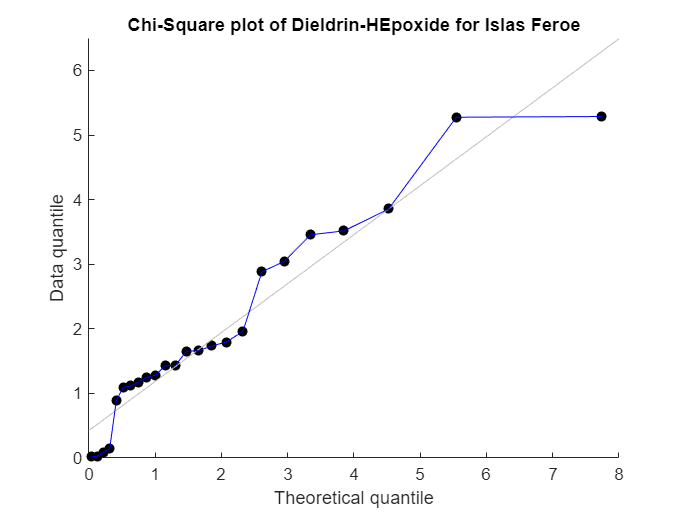


% Dimensiones 1-4 para Islas Feroe
x1x4_f = [x1_feroe x4_feroe];
mean2 = mean(x1x4_f);
cov2 = cov(x1x4_f);
d_x1x4_f = diag((x1x4_f-mean2)*inv(cov2)*transpose(x1x4_f-mean2)); 
scatter(q_chi_f, sort(d_x1x4_f), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-HEpoxide for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x1x4_f), 'b');
hold off

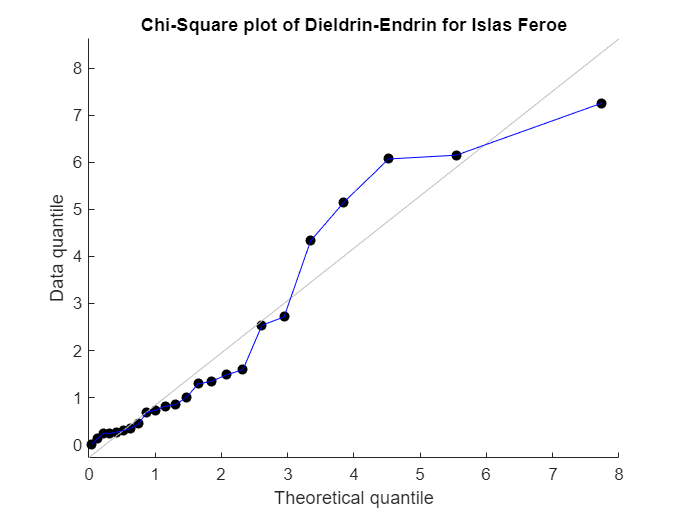


% Dimensiones 1-5 para Islas Feroe
x1x5_f = [x1_feroe x5_feroe];
mean3 = mean(x1x5_f);
cov3 = cov(x1x5_f);
d_x1x5_f = diag((x1x5_f-mean3)*inv(cov3)*transpose(x1x5_f-mean3)); 
scatter(q_chi_f, sort(d_x1x5_f), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-Endrin for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x1x5_f), 'b');
hold off

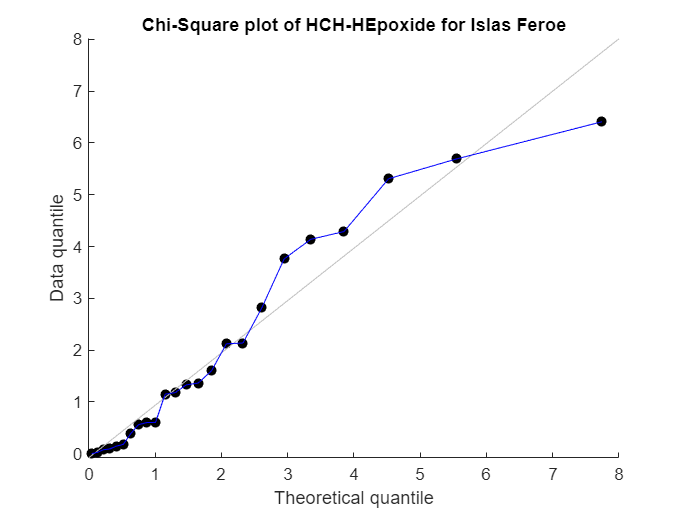


% Dimensiones 3-4 para Islas Feroe
x3x4_f = [x3_feroe x4_feroe];
mean4 = mean(x3x4_f);
cov4 = cov(x3x4_f);
d_x3x4_f = diag((x3x4_f-mean4)*inv(cov4)*transpose(x3x4_f-mean4)); 
scatter(q_chi_f, sort(d_x3x4_f), '', 'black');
refline;
hold on
title('Chi-Square plot of HCH-HEpoxide for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x3x4_f), 'b');
hold off

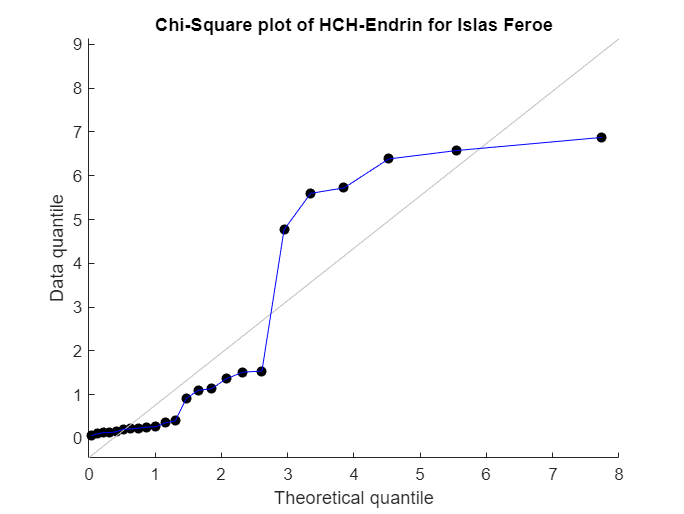


% Dimensiones 3-5 para Islas Feroe
x3x5_f = [x3_feroe x5_feroe];
mean5 = mean(x3x5_f);
cov5 = cov(x3x5_f);
d_x3x5_f = diag((x3x5_f-mean5)*inv(cov5)*transpose(x3x5_f-mean5)); 
scatter(q_chi_f, sort(d_x3x5_f), '', 'black');
refline;
hold on
title('Chi-Square plot of HCH-Endrin for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x3x5_f), 'b');
hold off

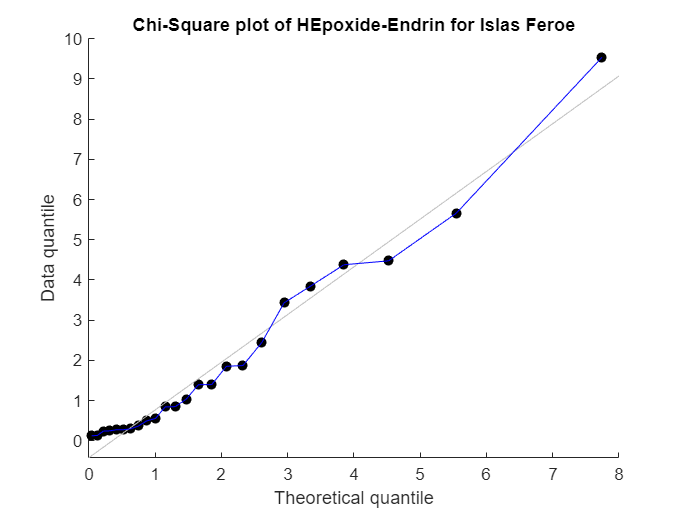


% Dimensiones 4-5 para Islas Feroe
x4x5_f = [x4_feroe x5_feroe];
mean6 = mean(x4x5_f);
cov6 = cov(x4x5_f);
d_x4x5_f = diag((x4x5_f-mean6)*inv(cov6)*transpose(x4x5_f-mean6)); 
scatter(q_chi_f, sort(d_x4x5_f), '', 'black');
refline;
hold on
title('Chi-Square plot of HEpoxide-Endrin for Islas Feroe');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_x4x5_f), 'b');
hold off

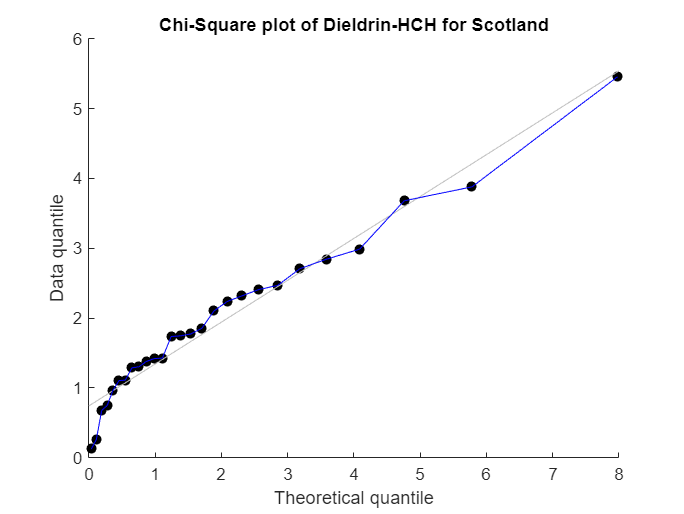


% Dimensiones 1-3 para Escocia
x1x3_s = [x1_scotland x3_scotland];
mean7 = mean(x1x3_s);
cov7 = cov(x1x3_s);
d_x1x3_s = diag((x1x3_s-mean7)*inv(cov7)*transpose(x1x3_s-mean7)); 
scatter(q_chi_s, sort(d_x1x3_s), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-HCH for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x1x3_s), 'b');
hold off

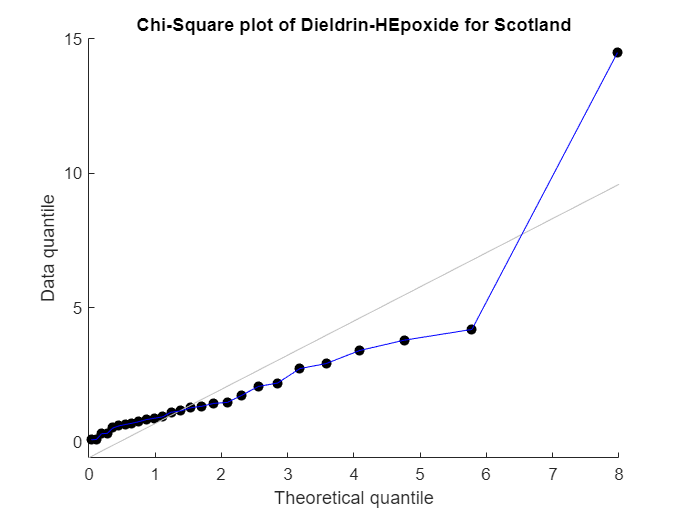


% Dimensiones 1-4 para Escocia
x1x4_s = [x1_scotland x4_scotland];
mean8 = mean(x1x4_s);
cov8 = cov(x1x4_s);
d_x1x4_s = diag((x1x4_s-mean8)*inv(cov8)*transpose(x1x4_s-mean8));
scatter(q_chi_s, sort(d_x1x4_s), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-HEpoxide for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x1x4_s), 'b');
hold off

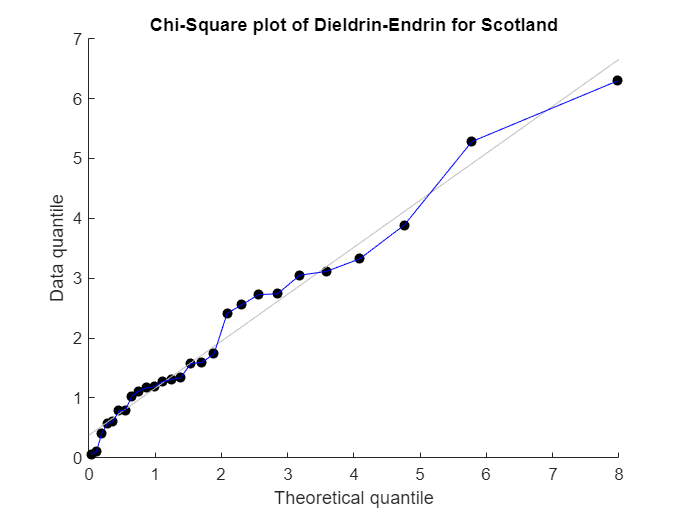


% Dimensiones 1-5 para Escocia
x1x5_s = [x1_scotland x5_scotland];
mean9 = mean(x1x5_s);
cov9 = cov(x1x5_s);
d_x1x5_s = diag((x1x5_s-mean9)*inv(cov9)*transpose(x1x5_s-mean9)); 
scatter(q_chi_s, sort(d_x1x5_s), '', 'black');
refline;
hold on
title('Chi-Square plot of Dieldrin-Endrin for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x1x5_s), 'b');
hold off

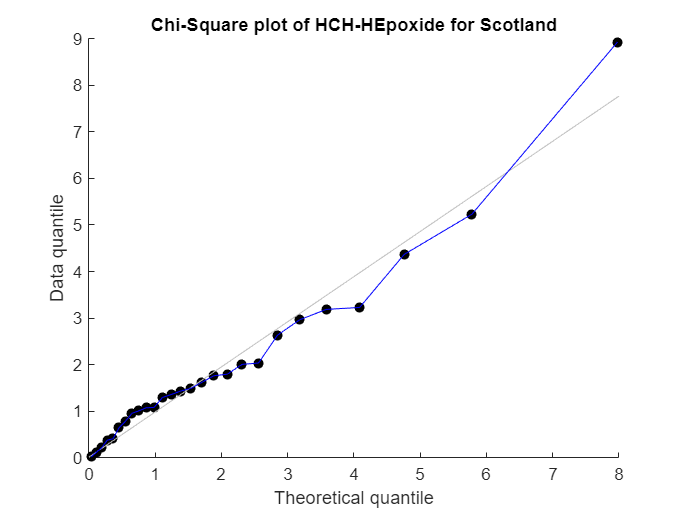


% Dimensiones 3-4 para Escocia
x3x4_s = [x3_scotland x4_scotland];
mean10 = mean(x3x4_s);
cov10 = cov(x3x4_s);
d_x3x4_s = diag((x3x4_s-mean10)*inv(cov10)*transpose(x3x4_s-mean10)); 
scatter(q_chi_s, sort(d_x3x4_s), '', 'black');
refline;
hold on
title('Chi-Square plot of HCH-HEpoxide for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x3x4_s), 'b');
hold off

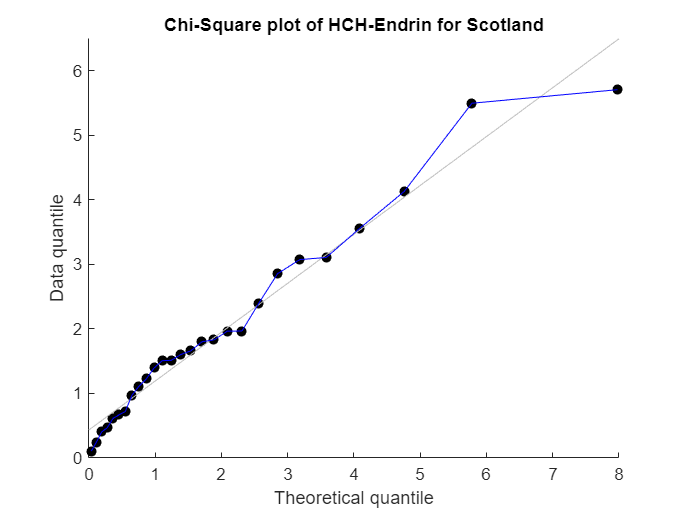


% Dimensiones 3-5 para Escocia
x3x5_s = [x3_scotland x5_scotland];
mean11 = mean(x3x5_s);
cov11 = cov(x3x5_s);
d_x3x5_s = diag((x3x5_s-mean11)*inv(cov11)*transpose(x3x5_s-mean11)); 
scatter(q_chi_s, sort(d_x3x5_s), '', 'black');
refline;
hold on
title('Chi-Square plot of HCH-Endrin for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x3x5_s), 'b');
hold off

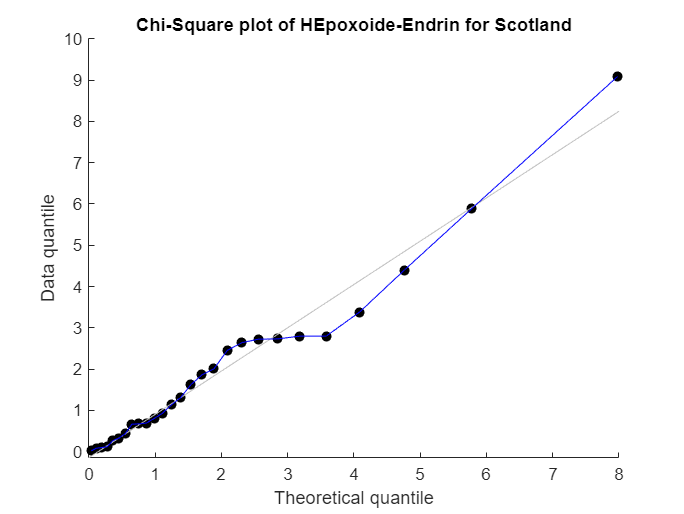


% Dimensiones 4-5 para Escocia
x4x5_s = [x4_scotland x5_scotland];
mean12 = mean(x4x5_s);
cov12 = cov(x4x5_s);
d_x4x5_s = diag((x4x5_s-mean12)*inv(cov12)*transpose(x4x5_s-mean12)); 
scatter(q_chi_s, sort(d_x4x5_s), '', 'black');
refline;
hold on
title('Chi-Square plot of HEpoxoide-Endrin for Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_x4x5_s), 'b');
hold off


% Para acabar de confirmar las sospechas sobre las dimensiones a escoger,
% miraremos la matriz con los coeficientes de correlación de cada una de 
% las dimensiones.
corrcoef([x1_feroe x3_feroe x4_feroe x5_feroe])

ans =     1.0000    0.8470    0.8777    0.1531
    0.8470    1.0000    0.7752    0.0275
    0.8777    0.7752    1.0000    0.2581
    0.1531    0.0275    0.2581    1.0000


**d) Assess multi-variate normality of all dimensions that have passed the tests from (b) and (c), considered jointly. **

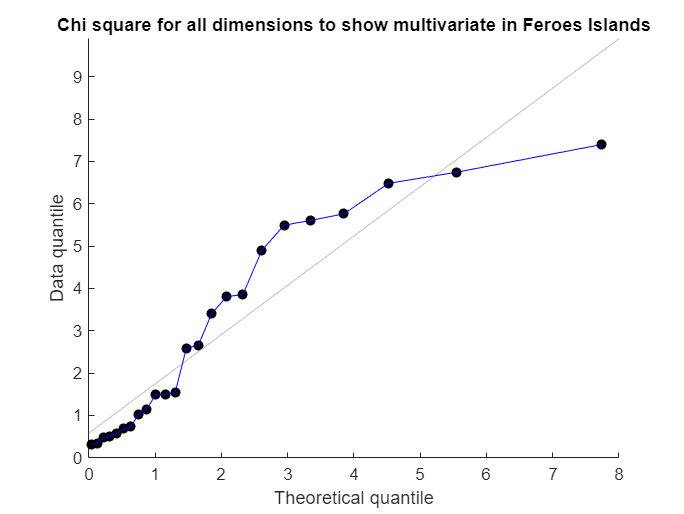

% Finalmente, para testear si estas dimensiones son "multi-variate" hacemos
% el Chi-Square plot para todas las dimensiones conjuntamente. En caso de que
% sigan algo similar a una línea recta, consideraremos que son "multi-variate".

% Feroe Islands
t_f = [x1_feroe x3_feroe x5_feroe];
meant_f = mean(t_f);
covt_f = cov(t_f);
d_t_f = diag((t_f-meant_f)*inv(covt_f)*transpose(t_f-meant_f));
scatter(q_chi_f, sort(d_t_f), '', 'black');
refline;
hold on
title('Chi square for all dimensions to show multivariate in Feroes Islands');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_f, sort(d_t_f), 'b');
hold off

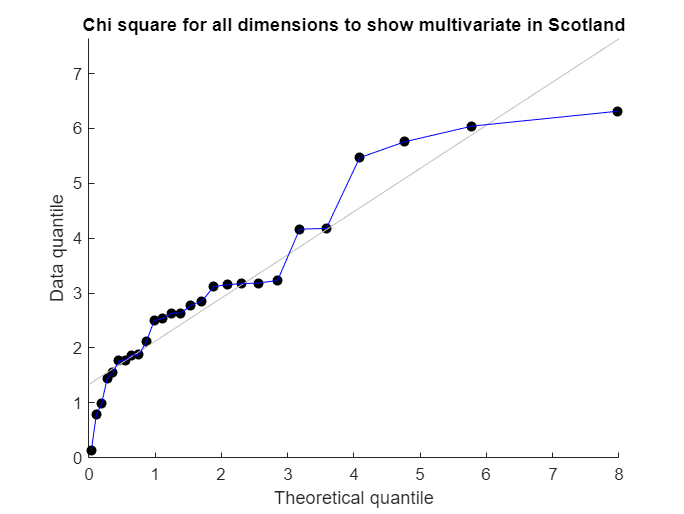


% Scotland
t_s = [x1_scotland x3_scotland x5_scotland];
meant_s = mean(t_s);
covt_s = cov(t_s);
d_t_s = diag((t_s-meant_s)*inv(covt_s)*transpose(t_s-meant_s));
scatter(q_chi_s, sort(d_t_s), '', 'black');
refline;
hold on
title('Chi square for all dimensions to show multivariate in Scotland');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi_s, sort(d_t_s), 'b');
hold off

**e) Based on all the above information, justify if any subset (or all) of the 5 provided contaminants can be analyzed under the multivariate normal assumption.**

En el apartado b), hemos llegado a la conclusión que las dimensiones 1,3,4 y 5 cumplían los requisitos para ser univariate. A continuación, en el apartado c), hemos visto que la dimensión 4 no se ajustaba tanto con las demás dimensiones, por lo que en este punto la hemos descartado y hemos seguido con las otras 3. Además, para asegurarnos, hemos mirado el coeficiente de correlación de cada una de las variables para ver que correlación tenian entre ellas. De allí hemos obtenido la información que las tres dimensiones seleccionadas son aquellas que tienen mayor correlación (más cercano a 1).

Finalmente, en el anterior apartado hemos visto que conjuntamente estas 3 dimensiones cumplen los requisitos y por lo tanto pueden ser analizadas bajo una asunción de Distribución normal multivariada.

**PROBLEM 2**

**a) State the null and alternative hypotheses to be tested. **


$$\begin{array}{l}
H_0 =\mu_1 -\mu_2 =\delta =0\\
H_A =\mu_1 -\mu_2 =\delta \not= 0
\end{array}$$
  
$$\textrm{with}\;\delta_0 =0$$


**b) From the different versions of Hotelling’s **$T^2$** that we have seen in class, indicate which one would be the most appropriate for this dataset and indicate what are the assumptions required for the model to be valid. **

Como en este caso tenemos 26 muestras para Feroe Islands y 27 para Scotland, y tenemos 5 dimensiones, estamos en el caso $b_1$, es decir, donde


$$\begin{array}{l}
n_1 -p\;\textrm{is}\;\textrm{not}\;\textrm{large}\\
n_2 -p\;\textrm{is}\;\textrm{not}\;\textrm{large}
\end{array}$$


Para que el modelo sea válido se han de cumplir las siguientes asunciones:

- 
$$\textrm{Random}\;\textrm{Sample}\;1\to \overrightarrow{X_{11} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{1n_1 } } \to \overrightarrow{\mu_1 } ,\;\Sigma_1$$


- 
$$\textrm{Random}\;\textrm{Sample}\;2\to \overrightarrow{X_{21} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{2n_2 } } \to \overrightarrow{\mu_2 } ,\;\Sigma_2$$


- 
$$\overrightarrow{X_{11} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{1n_1 } } \;\textrm{indep}\ldotp \overrightarrow{X_{21} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{2n_2 } } \;$$


Además, por estar en este caso añadimos dos asunciones más:

1) Similar covarianza.

2) Siguen una distribución Normal, es decir, que sean Gaussianas.

**c) Assess whether your dataset fulfills all the required assumptions. If any assumption is not fulfilled, you can proceed as in Problem 1 and simply reduce the subset of contaminants to those that do fulfill the required assumptions. **

A partir de los resultados del ejercicio 1, podemos deduir que nuestros datos siguen una distribución Normal. Para comprobar la otra asunción hemos de evaluar, estudiar, las covarianzas de ambas localizaciones.

S_f = cov(t_f);
S_s = cov(t_s);
if (S_f(1,1)/S_s(1,1) < 4) && (S_s(2,2)/S_f(2,2) < 4) && (S_f(3,3)/S_s(3,3) < 4)
    disp("They have Equal Covariance.");
else 
    disp("They have Different Covariance.");
end

They have Equal Covariance.


**d) Test the hypotheses stated in (a) at significance level α = 0.05. Indicate the conclusion that you reach regarding the research question. **

mean_f = mean(t_f);
mean_s = mean(t_s);
delta_0 = 0;
p = 3;
mean_sample = mean_f - mean_s;
Spool = ((n_f-1)*S_f+(n_s-1)*S_s)/(n_f+n_s-2);
estimator = (mean_sample-delta_0) * inv(Spool*((1/n_f)+(1/n_s))) * transpose(mean_sample-delta_0)

estimator = 35.1726

critic = ((n_f+n_s-2)/(n_s+n_f-1-p))*finv(1-0.05, p, n_f+n_s-1-p)

critic = 2.9216


if (estimator > critic)
    disp("We reject the null hypothesis at significance level 0.05.");
else 
    disp("We accept the null hypothesis at significance level 0.05.");
end

We reject the null hypothesis at significance level 0.05.


Como podemos ver a partir del resultado anterior, al ser el valor de nuestro estimador mayor al valor critico, podemos rechazar la hipotesis nula con un 95% de confianza. Es decir, que ambas localizaciones no tienen el mismo promedio de concentración de los contaminantes en el salmón estudiados, con un nivel de significación $\alpha =0\ldotp 05$. 

**e) Calculate 95% confidence intervals for each of the analyzed contaminants. Discuss whether they conform with the conclusion in (d). Shall this always be the case? Why? **

conf_interval_1 = [(mean_f(1)-mean_s(1)) + tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(1,1)*((1/n_f)+(1/n_s))) (mean_f(1)-mean_s(1)) - tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(1,1)*((1/n_f)+(1/n_s)))];
conf_interval_2 = [(mean_f(2)-mean_s(2)) + tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(2,2)*((1/n_f)+(1/n_s))) (mean_f(2)-mean_s(2)) - tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(2,2)*((1/n_f)+(1/n_s)))];
conf_interval_3 = [(mean_f(3)-mean_s(3)) + tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(3,3)*((1/n_f)+(1/n_s))) (mean_f(3)-mean_s(3)) - tinv((1-0.05)/(2*p), n_f+n_s-2) * sqrt(Spool(3,3)*((1/n_f)+(1/n_s)))];
conf_interval = [conf_interval_1 ; conf_interval_2 ; conf_interval_3]

conf_interval =    -0.6549   -0.3912
   -0.0581   -0.0320
    0.0746    0.1409


Al ver los intervalos, acabamos de confirmar lo que pensabamos en el apartado d), ya que no hay ninguna fila de estas 3 dimensiones tal que todos los valores de cada columna se encuentren dentro del intervalo. Por la cual cosa, claramente rechazamos la hipótesis nula.

Los intervalos de confianza nos indican dentro de que intervalos deberían estar los valores para no poder rechazar la $H_0$, es decir, que ambas localizaciones tendrían el mismo promedio de contaminantes. En caso contrario, como es el caso de nuestro problema, nos permite poder rechazar la hipótesis nula con un $\left(1-\alpha \right)100%$ de confianza.

**PROBLEM 3**

**a) State the null and alternative hypotheses to be tested.**


$$\begin{array}{l}
H_0 =\mu_1 -\mu_2 =\delta =0\\
H_A =\mu_1 -\mu_2 =\delta \not= 0
\end{array}$$
  
$$\textrm{with}\;\delta_0 =0$$


**b) Inspect the data and indicate what method would you use to test the hypotheses stated in (a). Clearly indicate the assumptions required by the method and justify why your data fulfills them.**


$$\begin{array}{l}
n_1 -p\;\textrm{is}\;\textrm{large}\\
n_2 -p\;\textrm{is}\;\textrm{also}\;\textrm{large}
\end{array}$$


Por lo tanto usaremos el caso de que ambos son "large", lo que tendremos que asumir es que:

- 
$$\textrm{Random}\;\textrm{Sample}\;1\to \overrightarrow{X_{11} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{1n_1 } } \to \overrightarrow{\mu_1 } ,\;\Sigma_1$$


- 
$$\textrm{Random}\;\textrm{Sample}\;2\to \overrightarrow{X_{21} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{2n_2 } } \to \overrightarrow{\mu_2 } ,\;\Sigma_2$$


- 
$$\overrightarrow{X_{11} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{1n_1 } } \;\textrm{indep}\ldotp \overrightarrow{X_{21} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{2n_2 } } \;$$
  

**c) Test the hypotheses stated in (a) at significance level α = 0.01. Indicate what conclusion do you reach and answer the research question.**

summer = [SM22Lab1Summer.NO2 SM22Lab1Summer.SO2];
winter = [SM22Lab1Winter.NO2 SM22Lab1Winter.SO2];
mean_1 = mean(summer);
mean_2 = mean(winter);
mean_sample = mean_1 - mean_2;
delta_0 = 0;
n_1 = length(summer);
n_2 = length(winter);
S_1 = cov(summer);
S_2 = cov(winter);
S = S_1/n_1 + S_2/n_2;
T = (mean_sample - delta_0) * inv(S) * transpose(mean_sample - delta_0)

T = 88.8136

T_critic = chi2inv(1-.01, 2)

T_critic = 9.2103

if (T > T_critic)
    disp("We reject the null hypothesis at significance level 0.01.");
else 
    disp("We accept the null hypothesis at significance level 0.01.");
end

We reject the null hypothesis at significance level 0.01.


Como podemos ver a partir del resultado anterior, al ser el valor de nuestro estimador mayor al valor critico, podemos rechazar la hipotesis nula con un 99% de confianza. Es decir, que en ambas estaciones tenemos diferentes niveles de polución del aire relacionada con SO2 y NO2, esto lo podemos asegurar con un nivel de significación $\alpha =0\ldotp 01$. Con el test realizado no podemos asegurar que haya mayor polución en invierno que en verano, solo que será diferente.

**d) Calculate and plot a 99% confidence region for the difference in population means. Discuss whether it conforms with the conclusion in (c). Shall this always be the case? Why?.**

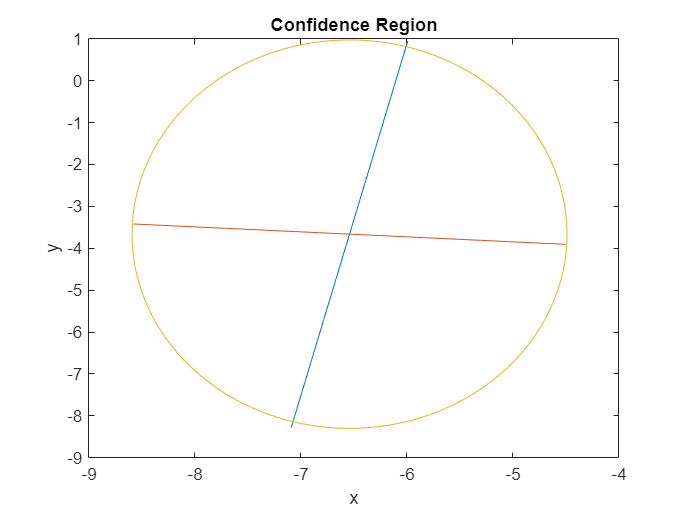

[U, E, V] = svd(S);
e_1 = U(:,1);
e_2 = U(:,2);
lambda_1 = E(1,1);
lambda_2 = E(2,2);
int_1 = [transpose(mean_sample)-sqrt(T_critic*lambda_1)*e_1 transpose(mean_sample)+sqrt(T_critic*lambda_1)*e_1];
int_2 = [transpose(mean_sample)-sqrt(T_critic*lambda_2)*e_2 transpose(mean_sample)+sqrt(T_critic*lambda_2)*e_2];
plot(int_1(1,:), int_1(2,:));
hold on
plot(int_2(1,:), int_2(2,:));
dist_1 = norm(int_1(:,1)-int_1(:,2))/2;
dist_2 = norm(int_2(:,1)-int_2(:,2))/2;
t=-pi:0.01:pi;
x = mean_sample(1)+dist_2*cos(t);
y = mean_sample(2)+dist_1*sin(t);
title("Confidence Region");
xlabel('x'); 
ylabel('y');
plot(x,y);
hold off

En este caso vemos como los valores tampoco estan todos dentro de la región de confianza, por la cual cosa confirmamos lo que deduciamos en el apartado c). 

Aunque la región de confianza nos da una cierta información, no podemos asegurar, únicamente a partir de ella, si rechazar o aceptar la $H_0$. Aún así nos podemos hacer una idea y a partir de otros estudios determinar si podemos o no aceptar la hipótesis nula.

Como ya hemos dicho en el apartado anterior y en este, con toda la información recopilada rechazamos la hipótesis nula con un $\left(1-\alpha \right)100%$ de confianza.